## MATLAB Live Script  for 2223-MA378: Linear Splines

Demonstrating convergences of piecewise linear ("linear spine") interpolation.  See also Section 2-1 of the lecture notes.

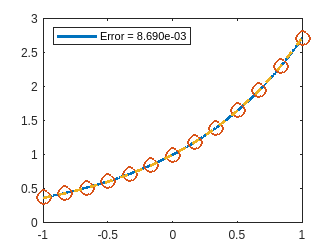

a=-1; b=1;
X = linspace(a,b,1001); 

f = @(x)exp(x);
n =12;
x = linspace(a,b,n+1);
l = @(X)interp1(x, f(x), X);
Error = max(abs(f(X)-l(X)));
plot(X, f(X), x, f(x), 'o', X, l(X), '--', 'LineWidth', 2, 'MarkerSize',10);
legend(sprintf("Error = %8.3e", Error), ...
   'Location','northwest');